# Моделирование работы  идеального диода

### 1. Построение ВАХ диода

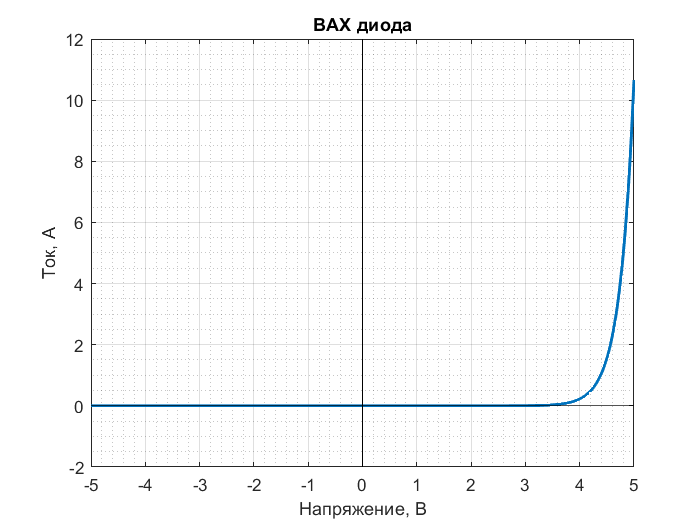

VR    = 0.01;    % разрешение по напряжению (Voltage Resolution)
CV    = 0.7;     % напряжение отсечки (Cutoff Voltage)
FR    = 0.4;     % прямое сопротивление (Forward Resistance)
RR    = 1e6;     % обратное сопротивление (Reverse Resistance)
tau   = 0.26;    % постоянная экспоненты ...
% (напряжение, за которое она увеличит свое значение в e-раз
V     = -5:VR:5; % диапазон изменения напряжения

Model = "Exponential"; % вид ВАХ диода: линейная или экспоненциальная
if Model == "Linear"
    CVC = 1/RR*V.*u1(-V)+1/FR*(V-CV).*u1(V-CV); ...
        % ВАХ (Current-Voltage Characteristic)
else 
    CVC = 1/RR*V.*u1(-V+CV)+CV/RR*exp((V-CV)/tau).*u0(V-CV); ...
        % ВАХ (Current-Voltage Characteristic)
end

figure;
axis = plot(V,CVC,'-','LineWidth',1.5);
title('ВАХ диода'); grid on; grid minor;
xlabel('Напряжение, В'); ylabel('Ток, A');
limX = [V(1) V(end)];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);

### 2. Формирование входного сигнала (напряжения)

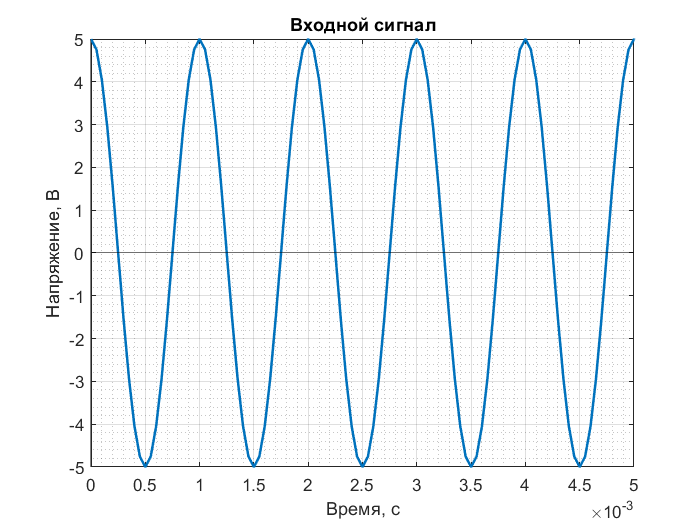

A     = +0.0;          % постоянная составляющая
B     = 5;             % амплитуда сигнала
f0    = 1e3;           % частота повторения сигнала
delta = 0.00/f0;       % задержка сигнала во времени
tmax  = 1.0;           % положение максимума относительно периода (д.б. [0;1])
q     = 2.0;           % скважность импульсов
fs    = 20*f0;         % частота дискретизации
dt    = 1/fs;          % период дискретизации
t     = 0:dt:10/f0-dt; % отсчеты времени
N     = length(t);     % кол-во отсчетов времени

Signal = "Sine Wave";
if Signal == "Sine Wave"
    Input = A+B*cos(2*pi*f0*(t+delta));
elseif Signal == "Sawtooth"
    Input = A+B*sawtooth(2*pi*f0*(t+delta),tmax);
elseif Signal == "Square"
    Input = A+B*square(2*pi*f0*(t+delta),100/q);
end

figure;
axis = plot(t,Input,'-','LineWidth',1.5);
title('Входной сигнал'); grid on; grid minor;
xlabel('Время, с'); ylabel('Напряжение, В');
limX = [t(1) (t(end)+dt)/2];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);

### 3. Вычисление выходного сигнала

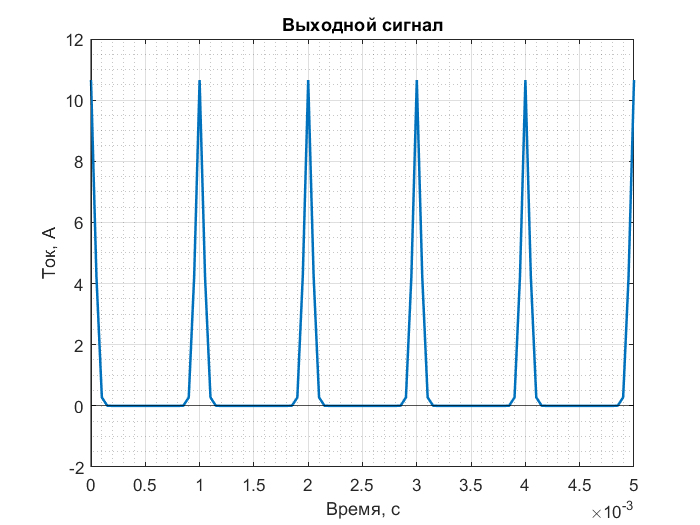

Output = zeros(1,N);
for i = 1:N
    [~,index] = min(abs(V-Input(i)));
    Output(i) = CVC(index);
end

figure;
axis = plot(t,Output,'-','LineWidth',1.5);
title('Выходной сигнал'); grid on; grid minor;
xlabel('Время, с'); ylabel('Ток, А');
limX = [t(1) (t(end)+dt)/2];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);

### 4. Спектральная оценка

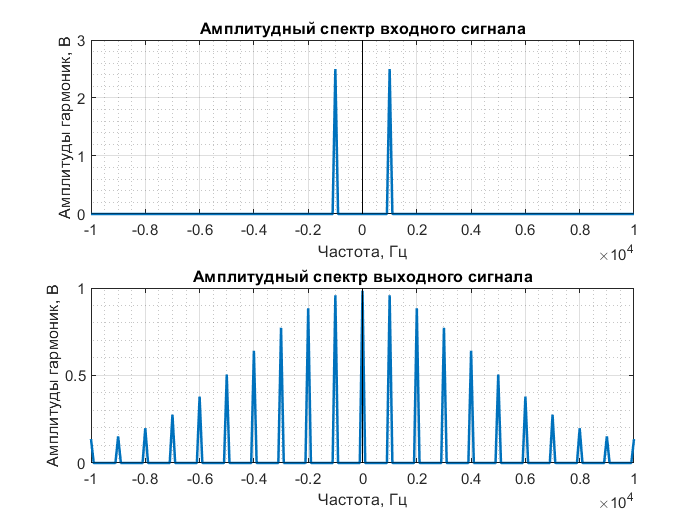

RBW = fs/N;                      % разрешение по частоте
FFTInput = fft(Input)/N;         % спектр входного сигнала
FFTOutput = fft(Output)/N;       % спектр выходного сигнала
FFTInput = fftshift(FFTInput);
FFTOutput = fftshift(FFTOutput);
if mod(N,2) == 0
    f = (-N/2:N/2)*RBW;
    FFTInput = [FFTInput FFTInput(1)];
    FFTOutput = [FFTOutput FFTOutput(1)];
else
    f = (-floor(N/2):floor(N/2))*RBW;
end

figure;
subplot(2,1,1);
axis = plot(f,abs(FFTInput),'-','LineWidth',1.5);
title('Амплитудный спектр входного сигнала'); grid on; grid minor;
xlabel('Частота, Гц'); ylabel('Амплитуды гармоник, В');
limX = [f(1) f(end)];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);
subplot(2,1,2);
axis = plot(f,abs(FFTOutput),'-','LineWidth',1.5);
title('Амплитудный спектр выходного сигнала'); grid on; grid minor;
xlabel('Частота, Гц'); ylabel('Амплитуды гармоник, В');
limX = [f(1) f(end)];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);

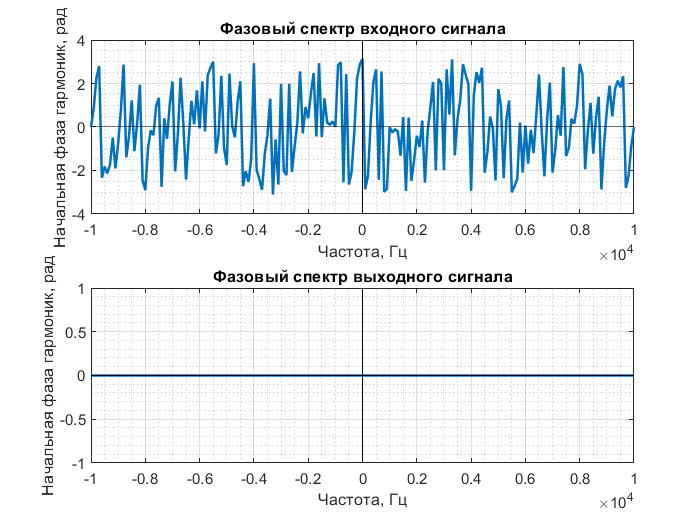


figure;
subplot(2,1,1);
axis = plot(f,angle(FFTInput),'-','LineWidth',1.5);
title('Фазовый спектр входного сигнала'); grid on; grid minor;
xlabel('Частота, Гц'); ylabel('Начальная фаза гармоник, рад');
limX = [f(1) f(end)];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);
subplot(2,1,2);
axis = plot(f,angle(FFTOutput),'-','LineWidth',1.5);
title('Фазовый спектр выходного сигнала'); grid on; grid minor;
xlabel('Частота, Гц'); ylabel('Начальная фаза гармоник, рад');
limX = [f(1) f(end)];
limY = axis.Parent.YLim;
line(limX,zeros(1,2),'Color','Black');
line(zeros(1,2),limY,'Color','Black');
xlim(limX); ylim(limY);